# Hodgkin-Huxley 10 Step Current Pulses

% Declare Global Parameter Values
Gl = 30e-9; % in Siemens
GNa = 12e-6; % in Siemens
Gk = 3.6e-6; % in Siemens
ENa = 45e-3; % in Volts (V)
Ek = -82e-3; % in V
El = -60e-3; % in V
Cm = 100e-12; % in Farads

% Set up time vector
t0 = 0;
dt = 0.1e-3;
t_max = .35; % in seconds
tvec = t0:dt:t_max;

% Create membrane potential vector
Vc = zeros(size(tvec));

% Call function applied_current to generate 10 step pulse current with
% parameters min delay = 5 ms, max delay = 25 ms, with 10 pulses, amplitude 0.22 nFarads.
APC = applied_current(tvec, 10, 50, 0.22e-9, 5, 25); %Applied current vector

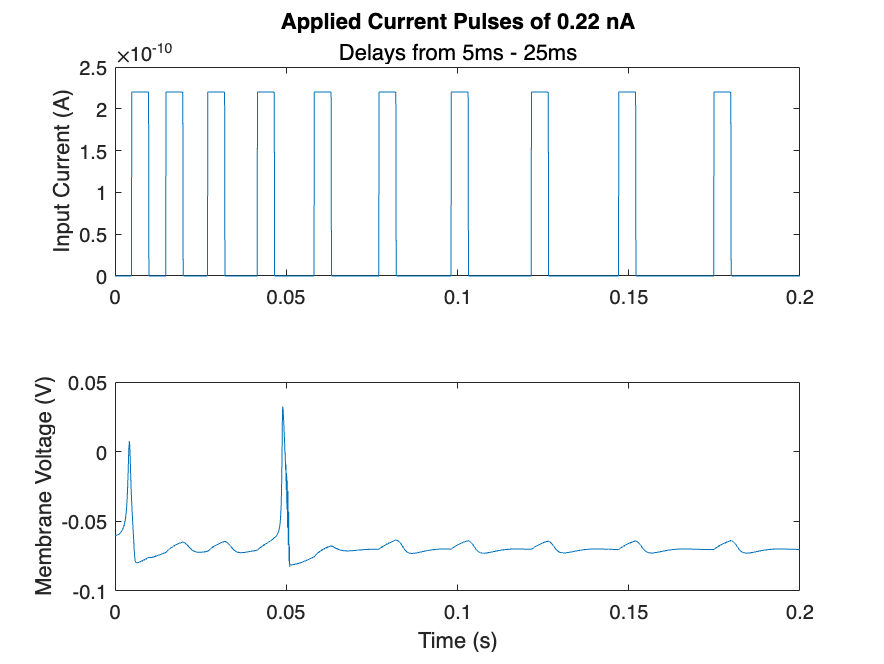


% Create gating variable vectors
mc = zeros(size(tvec));
hc = zeros(size(tvec));
nc = zeros(size(tvec));

% Initial Conditions
Vc(1) = El;
% Run Euler's Method
for i = 2:length(tvec)
    dVcdt = (1/Cm)*(Gl*(El-Vc(i-1)) + GNa*(mc(i-1)^3)*hc(i-1)*(ENa - Vc(i-1)) + Gk*(nc(i-1)^4)*(Ek-Vc(i-1)) + APC(i-1));
    Vc(i) = EM(Vc(i-1), dVcdt, dt);
    dmcdt = alphaM(Vc(i-1))*(1-mc(i-1)) - betaM(Vc(i-1))*mc(i-1);
    mc(i) = EM(mc(i-1), dmcdt, dt);
    dhcdt = alphaH(Vc(i-1))*(1-hc(i-1)) - betaH(Vc(i-1))*hc(i-1);
    hc(i) = EM(hc(i-1), dhcdt, dt);
    dncdt = alphaN(Vc(i-1))*(1-nc(i-1)) - betaN(Vc(i-1))*nc(i-1);
    nc(i) = EM(nc(i-1), dncdt, dt);
end

% Plot Figures
figure;
subplot(2,1,1)
x = tvec;
y1 = APC;
plot(x, y1)
xlim([0 0.2]);
title('Applied Current Pulses of 0.22 nA','Delays from 5ms - 25ms')
ylabel('Input Current (A)')
subplot(2,1,2)
y2 = Vc;
plot(x, y2)
xlim([0 0.2]);
xlabel('Time (s)')
ylabel('Membrane Voltage (V)')

function applied_current_vector = applied_current(tvec, pulses, duration, amplitude, dmin, dmax)
% Applied Current Vector function generates the current vector used in this
% simulation. 
% Takes tvec, number of pulses, duration of pulse, amplitude, the minumum
% delay duration and the maximum delay duration as arguments and returns
% the current vector.

    % Initialize the output vector to zeros
    applied_current_vector = zeros(size(tvec));
    delay_times = linspace(dmin*10,dmax*10,pulses);
    % Loop through each pulse
    for i = 1:pulses
        % Find the start time of the current pulse
        if i == 1
        start_time = delay_times(i);
        else
        start_time = start_time + duration + delay_times(i-1);
        end
% Set the values of applied_current_vector to amplitude during the pulse
    applied_current_vector(start_time : start_time+duration-1) = amplitude;
    end
end

function y = EM(a, b, c) %Euler's Method Function
y = a + b*c;
end
function y = alphaM(x)
if exp(100*(-x-0.045))-1 == 0 % Checks for division by zero to prevent
errors
y = 0;
else
y = ((10^5)*(-x-0.045))/(exp(100*(-x-0.045))-1);
end
end
function y = betaM(x)
y = 4*(10^3)*exp((-x-0.070)/0.018);
end
function y = alphaH(x)
y = 70*exp(50*(-x-0.070));
end
function y = betaH(x)
y = 10^3/(1 + exp(100*(-x-0.040)));
end
function y = alphaN(x)
if exp(100*(-x-0.060))-1 == 0
y = 0;
else
y = ((10^4)*(-x-0.060))/(exp(100*(-x-0.060))-1);
end
end
function y = betaN(x)
y = 125*exp((-x-0.070)/0.08);
end
